Vaja 3

clear all; clc

Nalaganje podatkov v matlab

nir = dir(['oseba*.nir']);
ldf = dir(['oseba*.ldf']);
po2 = dir(['oseba*.po2']);

for ii=1:6
    os(ii).nir=load(nir(ii).name);
    os(ii).ldf=load(ldf(ii).name);
    os(ii).po2=load(po2(ii).name);
end

Grafi

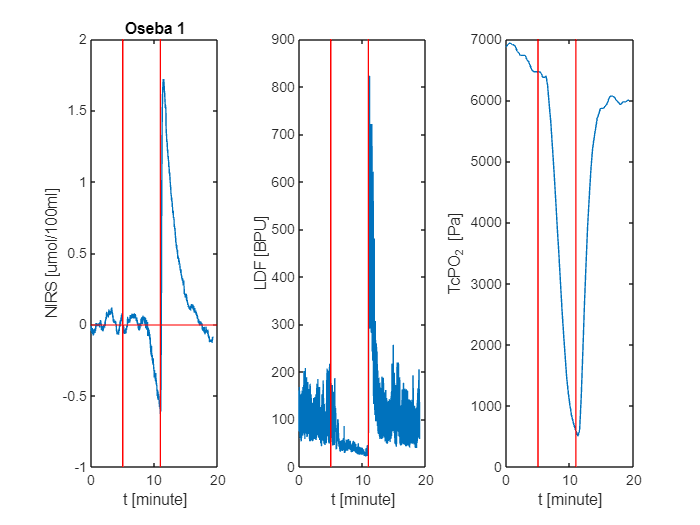

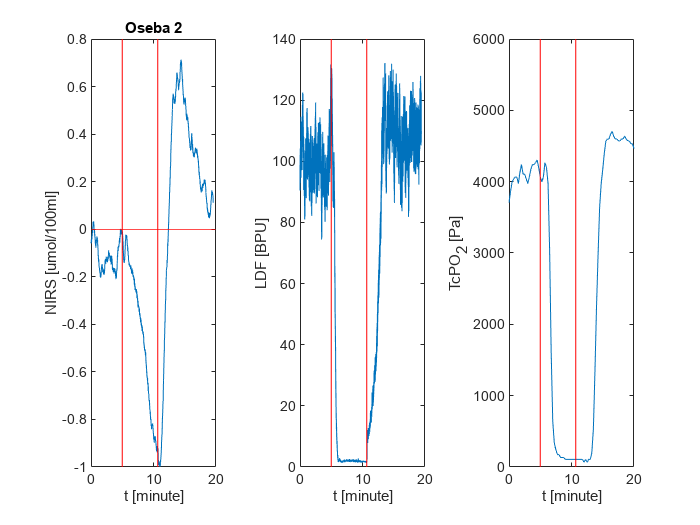

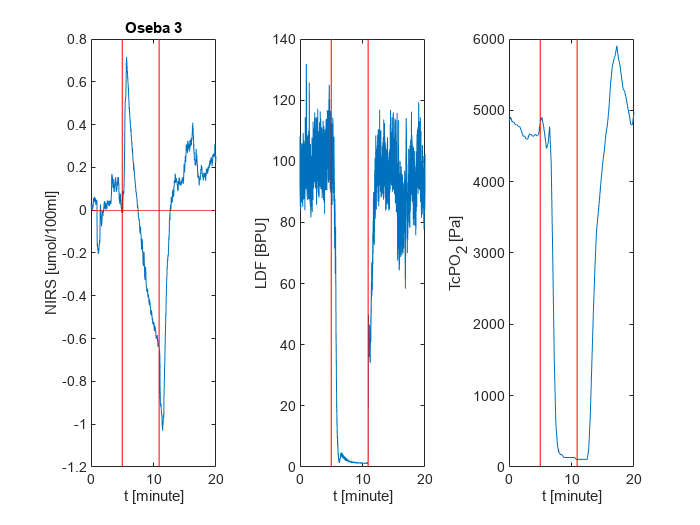

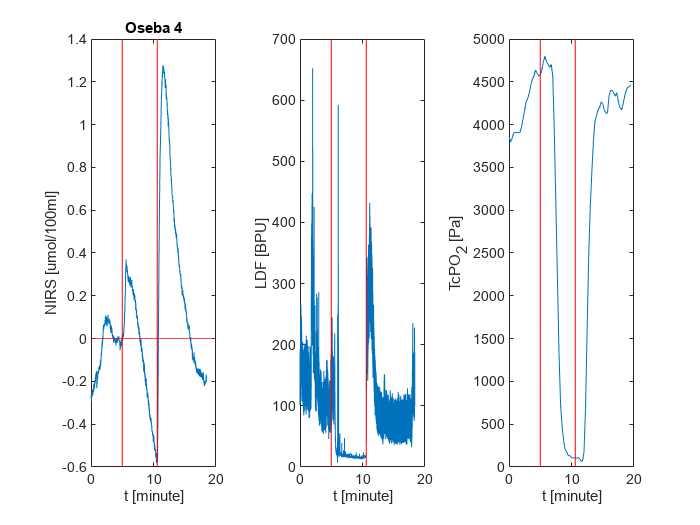

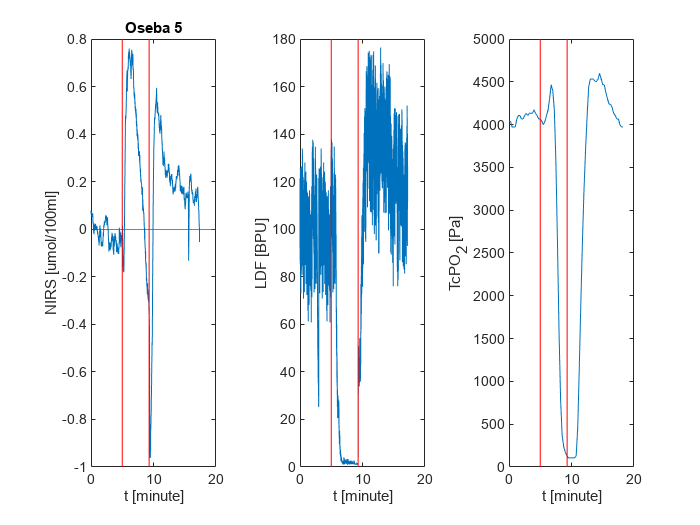

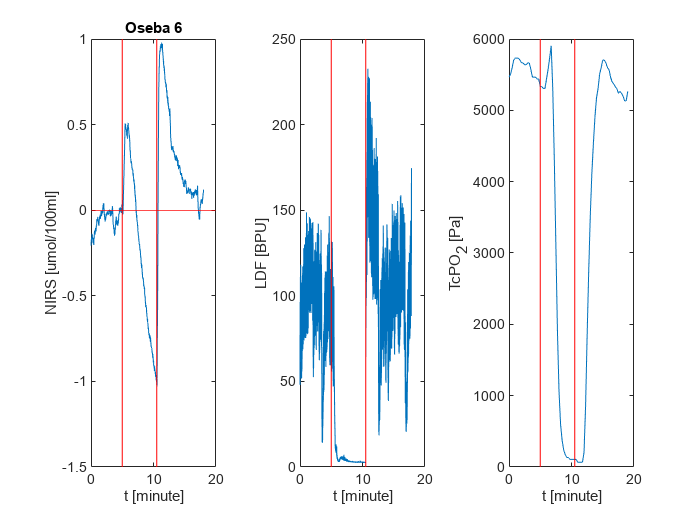

for ii = 1:6
    i_1(ii) = find(os(ii).ldf(:,3) == 1, 1, 'first'); 
    j_1(ii) = find(os(ii).ldf(:,3) == 2, 1, 'first');
    os(ii).po2(:,2)=os(ii).po2(:,2)*133.3;
    
    naslov = ['Oseba ' num2str(ii)];
    
    figure;
    tiledlayout(1, 3);
    nexttile;
    plot(os(ii).nir(:,1), os(ii).nir(:,2)); 
    xlabel('t [minute]'); 
    ylabel('NIRS [umol/100ml]');
    title(naslov)
    line([os(ii).ldf(i_1(ii)) os(ii).ldf(i_1(ii))], ylim, 'color', 'r');
    line([os(ii).ldf(j_1(ii)) os(ii).ldf(j_1(ii))], ylim, 'color', 'r');
    yline(0,'color', 'r');
    h = axis;
    axis([0,20,h(3),h(4)])
    
    nexttile; 
    plot(os(ii).ldf(:,1), os(ii).ldf(:,2)); 
    xlabel('t [minute]');
    ylabel('LDF [BPU]');
    line([os(ii).ldf(i_1(ii)) os(ii).ldf(i_1(ii))], ylim, 'color', 'r');
    line([os(ii).ldf(j_1(ii)) os(ii).ldf(j_1(ii))], ylim, 'color', 'r');
    h = axis;
    axis([0,20,h(3),h(4)])
    
    nexttile; 
    plot(os(ii).po2(:,1), os(ii).po2(:,2)); 
    xlabel('t [minute]'); 
    ylabel('TcPO_2 [Pa]');
    line([os(ii).ldf(i_1(ii)) os(ii).ldf(i_1(ii))], ylim, 'color', 'r');
    line([os(ii).ldf(j_1(ii)) os(ii).ldf(j_1(ii))], ylim, 'color', 'r');
    h = axis;
    axis([0,20,h(3),h(4)])
    
end

Izračun MR

MR_Hb(:,1)=1:6;
tR_Hb(:,1)=1:6;
tM_Hb(:,1)=1:6;
S_Hb(:,1)=1:6;
kisik(:,1)=1:6;
MR_LDF(:,1)=1:6;
tR_LDF(:,1)=1:6;
tM_LDF(:,1)=1:6;
rO2(:,1)=1:6;
tH(:,1)=1:6;

% Poiščemo točke začetka in konca "zažema"

for ii = 1:6
    Hb_s(ii) = find(os(ii).nir(:,3) == 1, 1, 'first'); 
    Hb_e(ii) = find(os(ii).nir(:,3) == 2, 1, 'first');
    LDF_s(ii) = find(os(ii).ldf(:,3) == 1, 1, 'first'); 
    LDF_e(ii) = find(os(ii).ldf(:,3) == 2, 1, 'first');
    O2_s(ii) = find(os(ii).po2(:,3) == 1, 1, 'first'); 
    O2_e(ii) = find(os(ii).po2(:,3) == 2, 1, 'first');
end

% Določitev parametrov iz grafov. Zaradi velikih razlik med grafi je ta
% postopek narejen ročno.

% Oseba 1

MR_Hb(1,2)=100*max(os(1).nir(Hb_e(1):end,2))/abs(os(1).nir(Hb_e(1),2));
tR_Hb(1,2)=os(1).nir(666,1)-os(1).nir(661,1);
tM_Hb(1,2)=os(1).nir(683,1)-os(1).nir(661,1);
S_Hb(1,2)=sum(os(1).nir(666:1037,2))*(os(1).nir(2,1)-os(1).nir(1,1));
kisik(1,2)=-4*(-0.5441-0.01551)/(10.77-8.9);
MR_LDF(1,2)=800;
tR_LDF(1,2)=0.04;
tM_LDF(1,2)=0.15;
rO2(1,2)=6500;
tH(1,2)=1.5;

% Oseba 2

MR_Hb(2,2)=100*max(os(2).nir(Hb_e(2):end,2))/abs(os(2).nir(Hb_e(2),2));
tR_Hb(2,2)=os(2).nir(745,1)-os(2).nir(646,1);
tM_Hb(2,2)=os(2).nir(827,1)-os(2).nir(646,1);
S_Hb(2,2)=sum(os(2).nir(745:1137,2))*(os(2).nir(2,1)-os(2).nir(1,1));
kisik(2,2)=-4*(-0.6259-0.01528)/(9.017-6.383);
MR_LDF(2,2)=100*os(2).ldf(8142,2)/os(2).ldf(3000,2);
tR_LDF(2,2)=os(2).ldf(7847,1)-os(2).ldf(6412,1);
tM_LDF(2,2)=os(2).ldf(8142,1)-os(2).ldf(6412,1);
rO2(2,2)=os(2).po2(20,2);
tH(2,2)=os(2).po2(57,1) -os(2).po2(45,1);

% Oseba 3

MR_Hb(3,2)=100*max(os(3).nir(Hb_e(3):end,2))/abs(os(3).nir(Hb_e(3),2));
tR_Hb(3,2)=os(3).nir(762,1)-os(3).nir(660,1);
tM_Hb(3,2)=os(3).nir(980,1)-os(3).nir(660,1);
S_Hb(3,2)=sum(os(3).nir(762:end,2))*(os(3).nir(2,1)-os(3).nir(1,1));
kisik(3,2)=-4*(-0.4316-0.3697)/(9.267-6.367);
MR_LDF(3,2)=100*os(3).ldf(7647,2)/os(3).ldf(3000,2);
tR_LDF(3,2)=os(3).ldf(7200,1)-os(3).ldf(6542,1);
tM_LDF(3,2)=os(3).ldf(7647,1)-os(3).ldf(6542,1);
rO2(3,2)=os(3).po2(20,2);
tH(3,2)=os(3).po2(55,1) -os(3).po2(45,1);

% Oseba 4

MR_Hb(4,2)=100*max(os(4).nir(Hb_e(4):end,2))/abs(os(4).nir(Hb_e(4),2));
tR_Hb(4,2)=os(4).nir(649,1)-os(4).nir(639,1);
tM_Hb(4,2)=os(4).nir(700,1)-os(4).nir(639,1);
S_Hb(4,2)=sum(os(4).nir(649:950,2))*(os(4).nir(2,1)-os(4).nir(1,1));
kisik(4,2)=-4*(-0.3025-0.1344)/(9.233-7.5);
MR_LDF(4,2)=100*os(4).ldf(6702,2)/os(4).ldf(3000,2);
tR_LDF(4,2)=os(4).ldf(6371,1)-os(4).ldf(6361,1);
tM_LDF(4,2)=os(4).ldf(6702,1)-os(4).ldf(6361,1);
rO2(4,2)=os(4).po2(21,2);
tH(4,2)=os(4).po2(52,1) -os(4).po2(45,1);

% Oseba 5

MR_Hb(5,2)=100*max(os(5).nir(Hb_e(5):end,2))/abs(os(5).nir(Hb_e(5),2));
tR_Hb(5,2)=os(5).nir(597,1)-os(5).nir(562,1);
tM_Hb(5,2)=os(5).nir(631,1)-os(5).nir(562,1);
S_Hb(5,2)=sum(os(5).nir(597:938,2))*(os(5).nir(2,1)-os(5).nir(1,1));
kisik(5,2)=-4*(0.1844-0.5558)/(8.1-6.917);
MR_LDF(5,2)=100*os(5).ldf(6523,2)/os(5).ldf(3000,2);
tR_LDF(5,2)=os(5).ldf(6028,1)-os(5).ldf(5583,1);
tM_LDF(5,2)=os(5).ldf(6523,1)-os(5).ldf(5583,1);
rO2(5,2)=os(5).po2(20,2);
tH(5,2)=os(5).po2(48,1) -os(5).po2(41,1);

% Oseba 6

MR_Hb(6,2)=100*max(os(6).nir(Hb_e(6):end,2))/abs(os(6).nir(Hb_e(6),2));
tR_Hb(6,2)=os(6).nir(645,1)-os(6).nir(636,1);
tM_Hb(6,2)=os(6).nir(680,1)-os(6).nir(636,1);
S_Hb(6,2)=sum(os(6).nir(645:1033,2))*(os(6).nir(2,1)-os(6).nir(1,1));
kisik(6,2)=-4*(-0.5246-(-0.04481))/(8.683-7.3);
MR_LDF(6,2)=100*os(6).ldf(6513,2)/os(6).ldf(3000,2);
tR_LDF(6,2)=os(6).ldf(6333,1)-os(6).ldf(6309,1);
tM_LDF(6,2)=os(6).ldf(6513,1)-os(6).ldf(6309,1);
rO2(6,2)=os(6).po2(20,2);
tH(6,2)=os(6).po2(52,1) -os(6).po2(45,1);

% Izpis vrednosti

MR_Hb

MR_Hb =     1.0000  297.4057
    2.0000   76.0445
    3.0000   61.4036
    4.0000  219.8717
    5.0000  145.0049
    6.0000   99.4208


tR_Hb

tR_Hb =     1.0000    0.0833
    2.0000    1.6500
    3.0000    1.7000
    4.0000    0.1667
    5.0000    0.5833
    6.0000    0.1500


tM_Hb

tM_Hb =     1.0000    0.3667
    2.0000    3.0167
    3.0000    5.3333
    4.0000    1.0167
    5.0000    1.1500
    6.0000    0.7333


S_Hb

S_Hb =     1.0000    3.3816
    2.0000    2.4666
    3.0000    1.8062
    4.0000    3.0102
    5.0000    1.5010
    6.0000    2.3641


MR_LDF

MR_LDF =     1.0000  800.0000
    2.0000  112.2807
    3.0000  128.4031
    4.0000  574.5763
    5.0000  155.3506
    6.0000  231.3499


tR_LDF

tR_LDF =     1.0000    0.0400
    2.0000    2.3917
    3.0000    1.0967
    4.0000    0.0167
    5.0000    0.7417
    6.0000    0.0400


tM_LDF

tM_LDF =     1.0000    0.1500
    2.0000    2.8833
    3.0000    1.8417
    4.0000    0.5683
    5.0000    1.5667
    6.0000    0.3400


rO2

rO2 = 1.0e+03 *

    0.0010    6.5000
    0.0020    4.1990
    0.0030    4.6655
    0.0040    4.5722
    0.0050    4.0657
    0.0060    5.4386


tH

tH =     1.0000    1.5000
    2.0000    3.0000
    3.0000    2.5000
    4.0000    1.7500
    5.0000    1.7500
    6.0000    1.7500


[~,I_MR_Hb]=sort(MR_Hb(:,2),'descend');
[~,I_tR_Hb]=sort(tR_Hb(:,2),'ascend');
[~,I_tM_Hb]=sort(tM_Hb(:,2),'ascend');
[~,I_S_Hb]=sort(S_Hb(:,2),'descend');
[~,I_MR_LDF]=sort(MR_LDF(:,2),'descend');
[~,I_tR_LDF]=sort(tR_LDF(:,2),'ascend');
[~,I_tM_LDF]=sort(tM_LDF(:,2),'ascend');
[~,I_rO2]=sort(rO2(:,2),'descend');
[~,I_tH]=sort(tH(:,2),'ascend');


for i=1:6
MR_Hb(I_MR_Hb(i),3)=i;
tR_Hb(I_tR_Hb(i),3)=i;
tM_Hb(I_tM_Hb(i),3)=i;
S_Hb(I_S_Hb(i),3)=i;
MR_LDF(I_MR_LDF(i),3)=i;
tR_LDF(I_tR_LDF(i),3)=i;
tM_LDF(I_tM_LDF(i),3)=i;
rO2(I_rO2(i),3)=i;
tH(I_tH(i),3)=i;
end

MR_Hb

MR_Hb =     1.0000  297.4057    1.0000
    2.0000   76.0445    5.0000
    3.0000   61.4036    6.0000
    4.0000  219.8717    2.0000
    5.0000  145.0049    3.0000
    6.0000   99.4208    4.0000


tR_Hb

tR_Hb =     1.0000    0.0833    1.0000
    2.0000    1.6500    5.0000
    3.0000    1.7000    6.0000
    4.0000    0.1667    3.0000
    5.0000    0.5833    4.0000
    6.0000    0.1500    2.0000


tM_Hb

tM_Hb =     1.0000    0.3667    1.0000
    2.0000    3.0167    5.0000
    3.0000    5.3333    6.0000
    4.0000    1.0167    3.0000
    5.0000    1.1500    4.0000
    6.0000    0.7333    2.0000


S_Hb

S_Hb =     1.0000    3.3816    1.0000
    2.0000    2.4666    3.0000
    3.0000    1.8062    5.0000
    4.0000    3.0102    2.0000
    5.0000    1.5010    6.0000
    6.0000    2.3641    4.0000


MR_LDF

MR_LDF =     1.0000  800.0000    1.0000
    2.0000  112.2807    6.0000
    3.0000  128.4031    5.0000
    4.0000  574.5763    2.0000
    5.0000  155.3506    4.0000
    6.0000  231.3499    3.0000


tR_LDF

tR_LDF =     1.0000    0.0400    3.0000
    2.0000    2.3917    6.0000
    3.0000    1.0967    5.0000
    4.0000    0.0167    1.0000
    5.0000    0.7417    4.0000
    6.0000    0.0400    2.0000


tM_LDF

tM_LDF =     1.0000    0.1500    1.0000
    2.0000    2.8833    6.0000
    3.0000    1.8417    5.0000
    4.0000    0.5683    3.0000
    5.0000    1.5667    4.0000
    6.0000    0.3400    2.0000


rO2

rO2 = 1.0e+03 *

    0.0010    6.5000    0.0010
    0.0020    4.1990    0.0050
    0.0030    4.6655    0.0030
    0.0040    4.5722    0.0040
    0.0050    4.0657    0.0060
    0.0060    5.4386    0.0020


tH

tH =     1.0000    1.5000    1.0000
    2.0000    3.0000    6.0000
    3.0000    2.5000    5.0000
    4.0000    1.7500    2.0000
    5.0000    1.7500    3.0000
    6.0000    1.7500    4.0000


Tabela

T = ["Parameter" "Os1" "Os2" "Os3" "Os4" "Os5" "Os6"; 
    "tR_Hb" 1 5 6 3 4 2;
    "tM_Hb" 1 5 6 3 4 2;
    "MR_Hb" 1 5 6 2 3 4;
    "S_Hb" 1 3 5 2 6 4;
    "MR_LDF" 1 6 5 2 4 3;
    "tR_LDF" 3 6 5 1 4 2;
    "rO2" 1 5 3 4 6 2;
    "tH" 1 6 5 2 3 4]

T = 9×7 string array
    "Parameter"    "Os1"    "Os2"    "Os3"    "Os4"    "Os5"    "Os6"
    "tR_Hb"        "1"      "5"      "6"      "3"      "4"      "2"  
    "tM_Hb"        "1"      "5"      "6"      "3"      "4"      "2"  
    "MR_Hb"        "1"      "5"      "6"      "2"      "3"      "4"  
    "S_Hb"         "1"      "3"      "5"      "2"      "6"      "4"  
    "MR_LDF"       "1"      "6"      "5"      "2"      "4"      "3"  
    "tR_LDF"       "3"      "6"      "5"      "1"      "4"      "2"  
    "rO2"          "1"      "5"      "3"      "4"      "6"      "2"  
    "tH"           "1"      "6"      "5"      "2"      "3"      "4"  


Parametri ne razvrstijo vseh enako, vendar vseeno ne prehajanja med zdravo in bolano osebo.

% Diagnoza
O2Hb(:,1)=1:6;
LDF(:,1)=1:6;
TcPO2(:,1)=1:6;
Diag(:,1)=1:6;


O2Hb(:, 2) = (MR_Hb(:,3)+tR_Hb(:,3)+tM_Hb(:,3)+S_Hb(:,1))

O2Hb =      1     4
     2    17
     3    21
     4    12
     5    16
     6    14


LDF(:, 2) = MR_LDF(:,3)+tR_LDF(:,3)+tM_LDF(:,3)

LDF =      1     5
     2    18
     3    15
     4     6
     5    12
     6     7


TcPO2(:, 2) = rO2(:,3)+tH(:,3)

TcPO2 =      1     2
     2    11
     3     8
     4     6
     5     9
     6     6


Diag(:, 2) = O2Hb(:,2)+LDF(:,2)+TcPO2(:,2)

Diag =      1    11
     2    46
     3    44
     4    24
     5    37
     6    27



T2 = ["Metoda" "Os1" "Os2" "Os3" "Os4" "Os5" "Os6";
    "NIRS" 4 18 23 10 17 12;
    "LDF" 5 18 15 6 12 7;
    "TcPO2" 2 11 8 6 9 6;
    "Sum" 11 47 46 22 38 25]

T2 = 5×7 string array
    "Metoda"    "Os1"    "Os2"    "Os3"    "Os4"    "Os5"    "Os6"
    "NIRS"      "4"      "18"     "23"     "10"     "17"     "12" 
    "LDF"       "5"      "18"     "15"     "6"      "12"     "7"  
    "TcPO2"     "2"      "11"     "8"      "6"      "9"      "6"  
    "Sum"       "11"     "47"     "46"     "22"     "38"     "25" 



%Z B so označene najbolj bolane osebe, s b ostale bolane z Z pa zdrave

T3 = ["Metoda" "Os1" "Os2" "Os3" "Os4" "Os5" "Os6";
    "NIRS" "Z" "b" "B" "x" "x" "b";
    "LDF" "Z" "B" "b" "x" "x" "b";
    "TcPO2" "Z" "B" "b" "x" "x" "b"]

T3 = 4×7 string array
    "Metoda"    "Os1"    "Os2"    "Os3"    "Os4"    "Os5"    "Os6"
    "NIRS"      "Z"      "b"      "B"      "x"      "x"      "b"  
    "LDF"       "Z"      "B"      "b"      "x"      "x"      "b"  
    "TcPO2"     "Z"      "B"      "b"      "x"      "x"      "b"  


Vse metode ločijo med zdravimi in bolanimi

%Poraba kisika
[~,I_kisik]=sort(kisik(:,2),'ascend');

for i=1:6
kisik(I_kisik(i),3)=i;
end

kisik

kisik =     1.0000    1.1970    4.0000
    2.0000    0.9737    1.0000
    3.0000    1.1052    3.0000
    4.0000    1.0084    2.0000
    5.0000    1.2558    5.0000
    6.0000    1.3877    6.0000


            
[~,I_kisik]=sort(kisik(:,2),'descend');

for i=1:6
kisik(I_kisik(i),3)=i;
end

kisik

kisik =     1.0000    1.1970    3.0000
    2.0000    0.9737    6.0000
    3.0000    1.1052    4.0000
    4.0000    1.0084    5.0000
    5.0000    1.2558    2.0000
    6.0000    1.3877    1.0000


Ta način razvrščanja se nam ne sklada z našo diagnozo